clc; clear; close all;
s = tf('s');
den_G = s*(s+6.54);

%10-2)
%a)
K_a = 5;
G_a = K_a / den_G;
CL_a = G_a/(1+G_a);
BW_a = bandwidth(CL_a)

BW_a = 0.8616

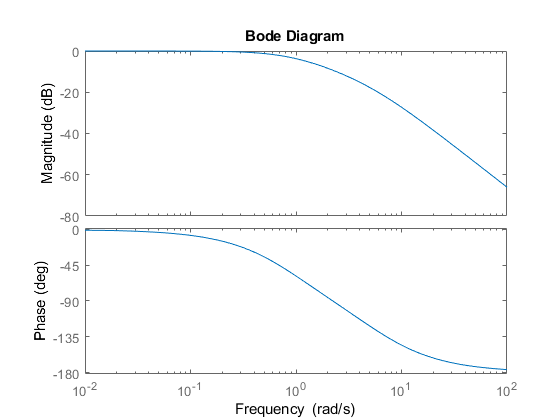

bode(CL_a);

%b)
K_b = 21.36;
G_b = K_b / den_G;
CL_b = G_b/(1+G_b);
BW_b = bandwidth(CL_b)

BW_b = 4.6134

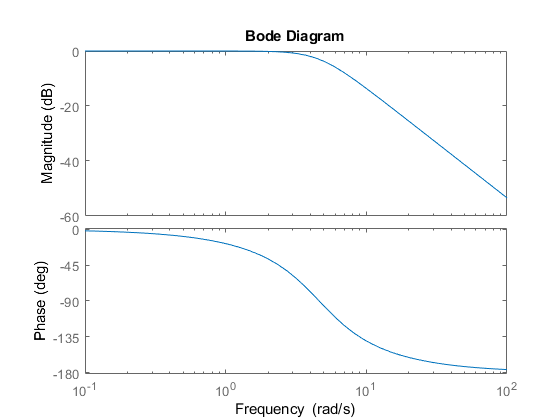

bode(CL_b);

%c)
K_c = 100;
G_c = K_c / den_G;
CL_c = G_c/(1+G_c);
BW_c = bandwidth(CL_c)

BW_c = 14.3398

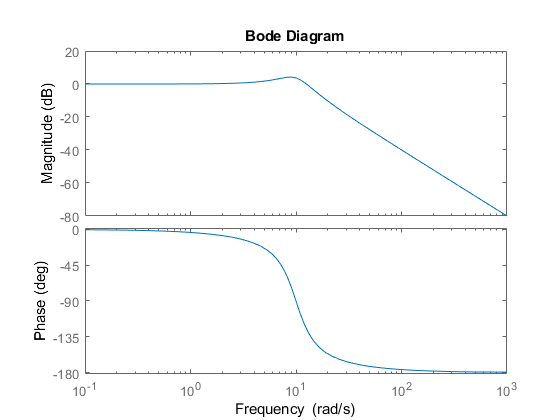

bode(CL_c);

%10-4
% e)
num_10_4_e = 0.5;
den_10_4_e = s*(s^2+s+1);
G_10_4_e = num_10_4_e/den_10_4_e;
CL_10_4_e = G_10_4_e/(1+G_10_4_e);
BW_10_4_e = bandwidth(CL_10_4_e)

BW_10_4_e = 1.0858

[Mr,wr] = getPeakGain(CL_10_4_e)

Mr = 1.5655

wr = 0.8086

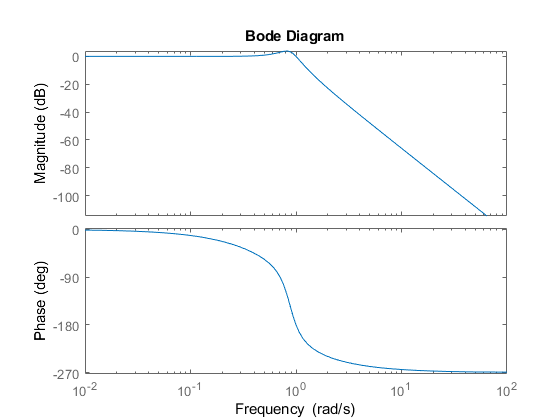

bode(CL_10_4_e);

%11.22
Kp = 6;
Ki = 1;
num_GH= 24*(Kp+Ki/s);
den_GH=s*(s+1)*(s+6);
GH=num_GH/den_GH;
%lead design
PL=55

PL = 55

CRover=15

CRover = 15

alpha=(1+sin(PL/180*pi))/(1-sin(PL/180*pi))

alpha = 10.0590

T=1/alpha^0.5/CRover

T = 0.0210

lead=(1+T*alpha*s)/(1+T*s)


lead =
 
  0.2114 s + 1
  -------------
  0.02102 s + 1
 
Continuous-time transfer function.



LT=GH*lead*lead %double lead compensation


LT =
 
             6.438 s^3 + 61.97 s^2 + 154.1 s + 24
  -----------------------------------------------------------
  0.0004418 s^6 + 0.04513 s^5 + 1.297 s^4 + 7.252 s^3 + 6 s^2
 
Continuous-time transfer function.



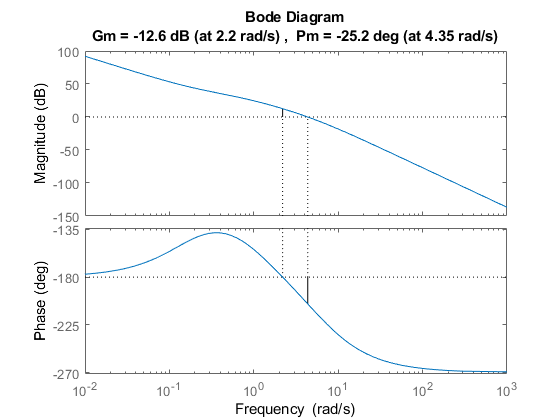

CL = LT/(1+LT);
figure(1)
margin(GH)

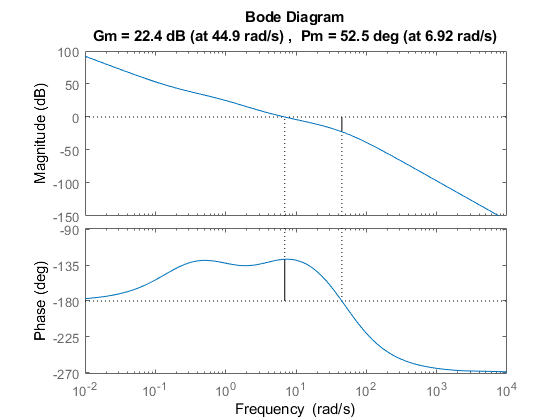

figure(2)
margin(LT)

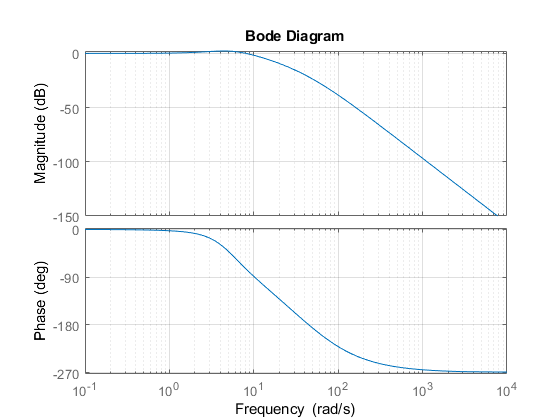

figure(3)
bode(CL)
grid on;